# **Simulation of Equations of Motion(Newton) - **the 3-LINK Robotic Manipulator 

## Introduction

In this **example** we're going to:

- Define the model parameters for our 3-LINK robotic manipulator.  

- Launch and Run a Simulink models that numerically solve the Equations of motion previously derived

-   - we'll watch the robot "collapse" under the influence of gravity

-   - we'll watch the robot write the word "hello"

- In each simulation, we'll compare the results produced by our hand derived model against the results produced by an alternate way of modelling this machine - a model created using Simscape Multibody.  Our expectation is that the results produced by both modelling techniques should be identical(very, very close). 

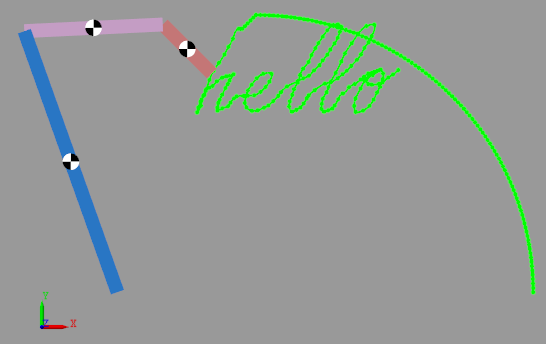

## The Background Story

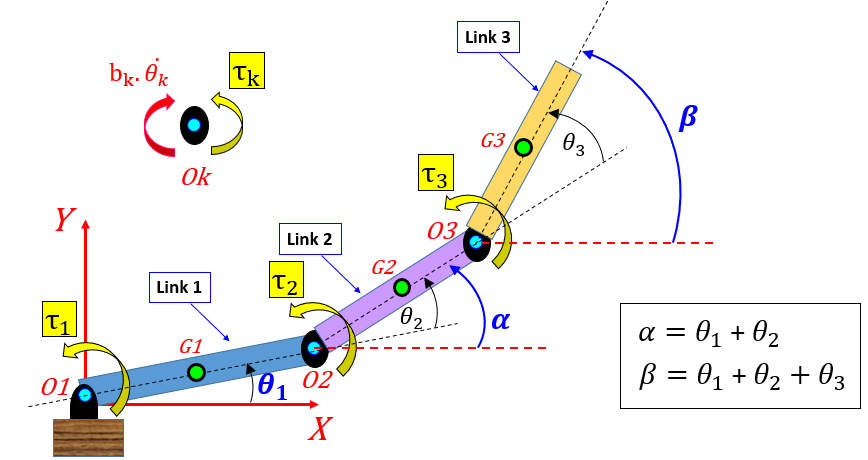

### What we'll be doing today:

In the script [`bh_3LINK_NEWTON_derivation.mlx`](matlab:  edit bh_3LINK_NEWTON_derivation.mlx), we used Newton's 2nd Law to derive the equations of motion for the 3-LINK robotic manipulator.  At the end of that exercise we converted the derived equations of motion into a Simulink block.  In today's tutorial(i.e. this tutorial) we'll explore a Simulink model that contains our hand derived equations of motion.  There are 3 main parts to todays tutorial:

- **PART_1:**  we'll define numeric values for our model parameters (e.g.  $b_1$,  $I_{\textrm{G2}}$ , etc)

- **PART_2:**  we'll open and run a Simulink model that simulates our 3-LINK robotic manipulator

- **PART_3:**  we'll open and run another  Simulink model that includes a control system that actuates the 3-LINK robotic manipulator

### How our derived equations will be used in the simulations:

Recall that in the script [`bh_3LINK_NEWTON_derivation.mlx`](matlab:  edit bh_3LINK_NEWTON_derivation.mlx)

-  We used Newton's 2nd Law to derive the equations of motion for the 3-LINK robotic manipulator.

- Specifically we computed the matrices $A$ and $\;b$ where:    $x\;=\;A\backslash b\;\;\;\;$will give us our 7 unknowns, i.e.:  $x\;=\;$${\left\lbrack \ddot{\beta} \;,\ddot{\alpha} \;,{\ddot{\theta} }_1 \;,R_{3X} \;,R_{3Y} \;,R_{2X} \;,R_{2Y} \right\rbrack }^T$ 

- At the end of our derivation we converted the derived equations into a Simulink block - the Simulink block contains the MATLAB code for computing our derived expressions for $A$ and $\;b$.

We have already placed this "yellow" block into a Simulink model file called **bh_COMPONENT_3LINK_hand_Newton.slx** - you'll  get to see it shortly !  Conceptually, we'll be using these derived equations of motion within Simulink, in the following way:

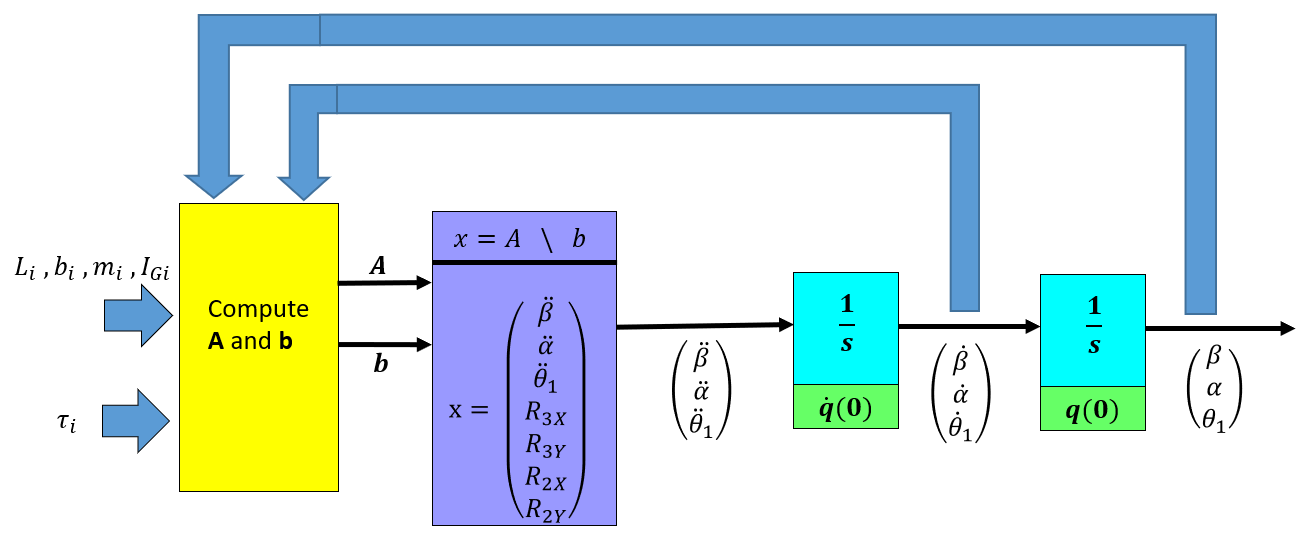

## Start with a clean and empty Workspace

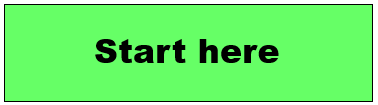

Let's clear the MATLAB workspace of any variables - we'll start this tutorial with a "clean slate".

clear

## PART_1:     Define parameters needed by the model

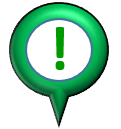**NOTE:**

- Shortly we'll be opening and running a Simulink model.  The Simulink model needs numerical values for the parameters of our 2-LINK robot.

- So in PART_1, we'll be defining these numerical values.

### Define some Material and Environment parameters

We'll represent each link in the pendulum as a rectangular prism(or BRICK).  So one of the first things we'll need are the inertia properties of the 2 links. We'll assume that each link has the same density.

robo_params.density = 1000;     % (kg/m3)
robo_params.g       = 9.80665;  % (m/sec^2)

### Define some Geometry and Mass parameters for Link 1

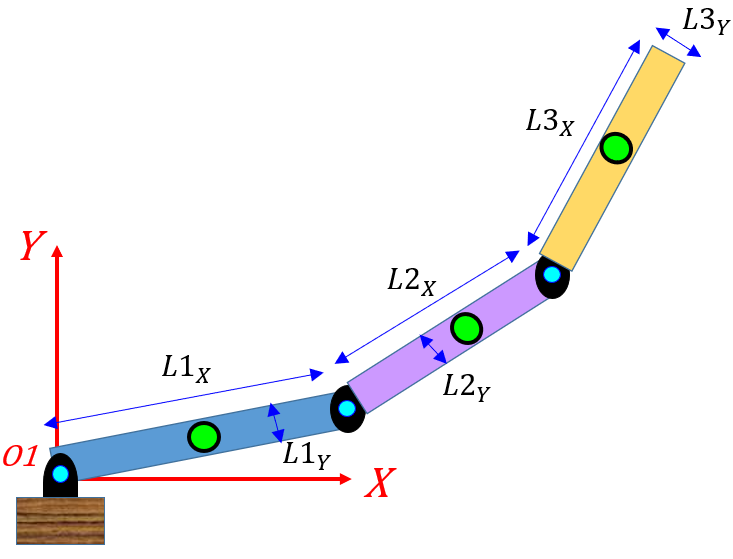

robo_params.L1x     = 1.000; % (m)
robo_params.L1y     = 0.050; % (m)
robo_params.L1z     = 0.005; % (m)
robo_params.L1xyz   = [robo_params.L1x,  robo_params.L1y,   robo_params.L1z];
robo_params.volume1 = robo_params.L1x * robo_params.L1y * robo_params.L1z;   % (m^3)
robo_params.mass1   = robo_params.density * robo_params.volume1;             % (kg)

Calculate the inertia of Link 1 about a $Z-\textrm{axis}$ passing through the center of mass $\textrm{G1}$ (eg: see [**HERE**](https://en.wikipedia.org/wiki/List_of_moments_of_inertia))

- 
$$I_{1G} \;\;=\;\;\frac{m_1 }{12}\ldotp \left(L_{1X}^2 \;\;+\;\;L_{1Y}^2 \;\right)$$


robo_params.I1g      = robo_params.mass1*(robo_params.L1x^2 + robo_params.L1y^2)/12;

Calculate the inertia of Link 1 about a $Z-\textrm{axis}$ passing through the pivot point $\textrm{O1}$ (using the parallel axis theorem):

- 
$$I_{1O} \;\;=\;\;I_{1G} \;\;\;\;+\;\;\;\;m_{1\;} \ldotp {\left(\frac{L_{1X} }{2}\right)}^2$$


robo_params.I1o      = robo_params.I1g  +  robo_params.mass1*(robo_params.L1x/2)^2;

### Define some Geometry and Mass parameters for Link 2

robo_params.L2x     = 0.500; % (m)
robo_params.L2y     = 0.050; % (m)
robo_params.L2z     = 0.005; % (m)
robo_params.L2xyz   = [robo_params.L2x,  robo_params.L2y,   robo_params.L2z];
robo_params.volume2 = robo_params.L2x * robo_params.L2y * robo_params.L2z; % (m^3)
robo_params.mass2   = robo_params.density * robo_params.volume2;           % (kg)

Calculate the inertia of Link 2 about a $Z-\textrm{axis}$ passing through the center of mass $\textrm{G2}$ 

robo_params.I2g      = robo_params.mass2*(robo_params.L2x^2 + robo_params.L2y^2)/12;

Calculate the inertia of Link 2 about a $Z-\textrm{axis}$ passing through the pivot point $\textrm{O2}$ (using the parallel axis theorem):

robo_params.I2o      = robo_params.I2g + robo_params.mass2*(robo_params.L2x/2)^2;

### Define some Geometry and Mass parameters for Link 3

robo_params.L3x     = 0.250; % (m)
robo_params.L3y     = 0.050; % (m)
robo_params.L3z     = 0.005; % (m)
robo_params.L3xyz   = [robo_params.L3x,  robo_params.L3y,   robo_params.L3z];
robo_params.volume3 = robo_params.L3x * robo_params.L3y * robo_params.L3z; % (m^3)
robo_params.mass3   = robo_params.density * robo_params.volume3;           % (kg)

Calculate the inertia of Link 3 about a $Z-\textrm{axis}$ passing through the center of mass $\textrm{G3}$ 

robo_params.I3g      = robo_params.mass3*(robo_params.L3x^2 + robo_params.L3y^2)/12;

Calculate the inertia of Link 3 about a $Z-\textrm{axis}$ passing through the pivot point $\textrm{O3}$ (using the parallel axis theorem):

robo_params.I3o      = robo_params.I3g + robo_params.mass3*(robo_params.L3x/2)^2;

### Define some damping at each revolute joint

We'll assume that each revolute joint applies viscous damping to the rigid bodies, ie: $\tau_{damping} = b \thinspace \dot{\theta}$.   

robo_params.b1_damp = 0.005; %0.1 (N.m/(rad/sec));
robo_params.b2_damp = 0.005; %0.1 (N.m/(rad/sec));
robo_params.b3_damp = 0.005; %0.1 (N.m/(rad/sec));

### Define the INITIAL Conditions

Recall the angular degrees of freedom of the machine:

 

Here are the system INITIAL conditions:

- $\left\lbrack \theta_1 \left(0\right),\;\;\;\theta_2 \left(0\right)\;,\;\theta_3 \left(0\right)\right\rbrack =\left\lbrack \frac{\pi }{3}\;,\;\frac{\pi }{4},\;\frac{\pi }{6}\;\;\right\rbrack$     `(rad)`

- $\left\lbrack {\dot{\theta} }_1 \left(0\right),\;{\dot{\theta} }_2 \left(0\right),\;{\dot{\theta} }_3 \left(0\right)\right\rbrack \;\;=\left\lbrack 0\ldotp 2,\;0\ldotp 1,\;0\ldotp 3\right\rbrack$  (`rad/sec)`

- $\alpha(0) = \theta_1(0) + \theta_2(0)$    `              (rad)`

- $\dot{\alpha}(0) = \dot{\theta}_1(0)  + \dot{\theta}_2(0) $                                (`rad/sec)`

- $\beta(0) = \theta_1(0) + \theta_2(0) + \theta_3(0)$    `        (rad)`

- $\dot{\beta}(0) = \dot{\theta}_1(0)  + \dot{\theta}_2(0)  + \dot{\theta}_3(0) $                   (`rad/sec)`

IC.theta1_0     = pi/3;          % (rad)
IC.theta2_0     = pi/4;          % (rad)
IC.theta3_0     = pi/6;          % (rad)
IC.theta1_dot_0 = 0.2;           % (rad/sec)
IC.theta2_dot_0 = 0.1;           % (rad/sec)
IC.theta3_dot_0 = 0.3;           % (rad/sec)
IC.alpha_0      = IC.theta1_0     +  IC.theta2_0;                           % (rad)
IC.beta_0       = IC.theta1_0     +  IC.theta2_0     +  IC.theta3_0;        % (rad)
IC.alpha_dot_0  = IC.theta1_dot_0 +  IC.theta2_dot_0;                       % (rad/sec)
IC.beta_dot_0   = IC.theta1_dot_0 +  IC.theta2_dot_0 + IC.theta3_dot_0;     % (rad/sec)

### Summarise what we've done so far

In PART_1 (above) we simply defined numerical values for our model parameters.  After executing the code in PART_1, your MATLAB workspace should now contain the following variables:

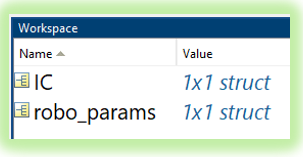

: Would you like to view the contents of these variables

[];

## PART_2:    Simulate a collapsing robot

In the first Simulink model that we'll look at, we assign rectangular torque pulses to $\tau_1 ,\tau_2 ,\tau_3$.  These applied torques are however NOT strong enough to overcome the effects of gravity ... and the 3-LINK robot simply "collapses".  

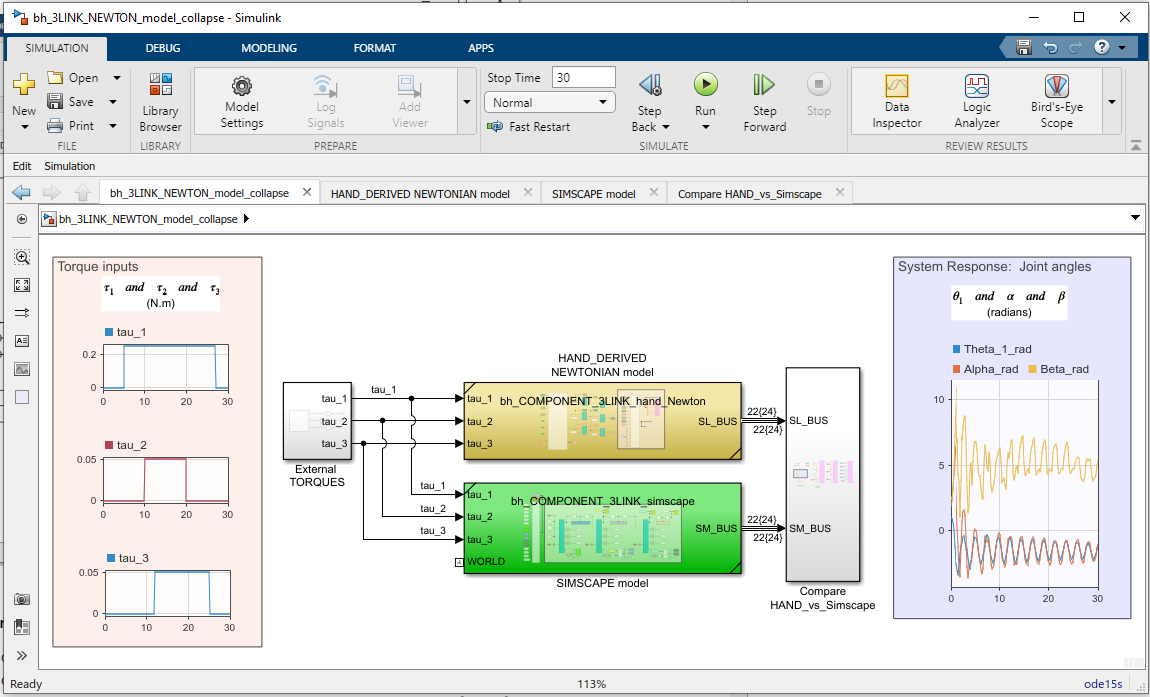

**NOTE:  After running the simulation, Have a look at ....**

- The contents inside the subsystem called "**HAND_DERIVED NEWTONIAN model**" - this contains our derived equations of motion

- The contents inside the subsystem called "**SIMSCAPE model**" - this contains an alternate approach to modelling the robot.  The ANIMATION that you see when you run the model is produced by Simscape(neat huh!)

- The scopes in the subsystem "**Compare HAND_vs_Simscape**".  We plot the time series response of $\theta_1 \;,\alpha \;,\beta$.  And we compare the HAND derived model responses against the Simscape model responses (they are both VERY VERY similar)

**Open the Simulink model:**

 

THE_MODEL = 'bh_3LINK_NEWTON_model_collapse.slx';

open_system(THE_MODEL)

When the Simulink model appears, you can run the model by clicking the green **Run** icon shown below

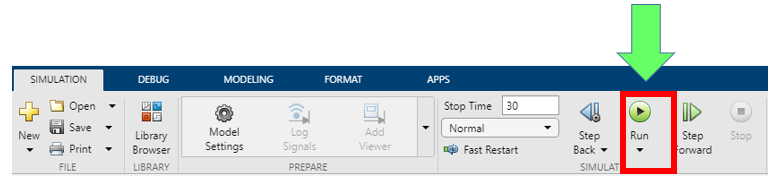

## PART_3:    Simulate a robot that writes hello

In the second Simulink model that we'll look at, we've included a Control system to produce the torques $\tau_1 \;,\tau_2 \;,\tau_3$ that makes the robot write **hello**  

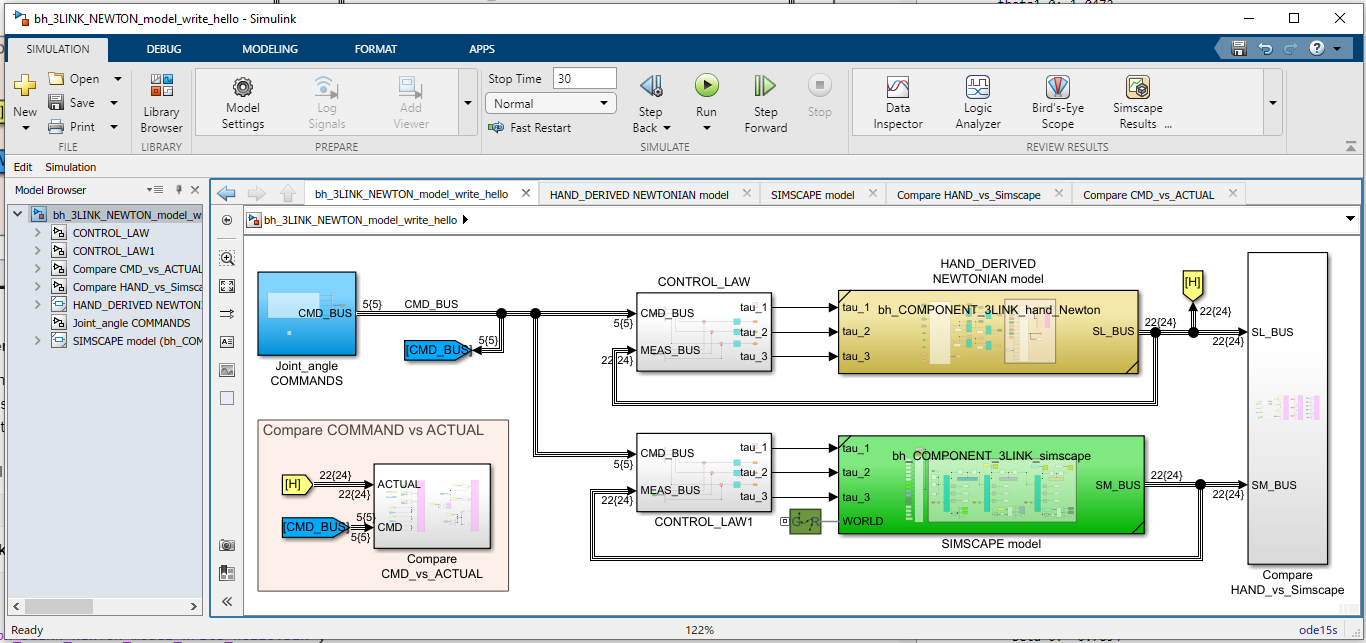

**NOTE:  After running the simulation, Have a look at ....**

- The contents inside the subsystem called "**CONTROL_LAW**" - this contains the controller that produces the torques $\tau_1 \;,\tau_2 \;,\tau_3$

- The scopes in the subsystem "**Compare CMD_vs_ACTUAL**".  We plot the time series response of the commanded joint angles ($\theta_1 \;,\theta_2 \;,\theta_1$) as well as the actual joint angles that the robot achieved.

For this model we'll specify a new set of model parameters:

[robo_params, IC, the_EE] = LOC_get_params_for_hello_robot();

**Open the Simulink model:**

 

THE_MODEL = 'bh_3LINK_NEWTON_model_write_hello.slx';

open_system(THE_MODEL)

# Next Steps

So far we've looked at deriving the equations of motion using Newton's approach.  There are alternate techniques for deriving these equations of motion, an example is the Langrangian approach. So? - So if you'd like to see how to derive the equations of motion of the 3-LINK manipulator using Lagrange's technque, then check out the following exercise

- [`bh_3LINK_LAGRANGE_derivation_AND_simulation.mlx`](matlab: edit bh_3LINK_LAGRANGE_derivation_AND_simulation)

# Local Subfunctions only beyond this point

Define parameters specifically for the robat that draws

function [robo_params, IC, the_EE] = LOC_get_params_for_hello_robot()
    
    robo_params.density = 1000;     % (kg/m3)
    robo_params.g       = 9.80665;  % (m/sec^2)
    
    robo_params.L1x     = 1.000; % (m)
    robo_params.L1y     = 0.050; % (m)
    robo_params.L1z     = 0.005; % (m)
    robo_params.L1xyz   = [robo_params.L1x,  robo_params.L1y,   robo_params.L1z];
    robo_params.volume1 = robo_params.L1x * robo_params.L1y * robo_params.L1z; % (m^3)
    robo_params.mass1   = robo_params.density * robo_params.volume1;           % (kg)
    robo_params.I1g      = robo_params.mass1*(robo_params.L1x^2 + robo_params.L1y^2)/12;
    robo_params.I1o      = robo_params.I1g  +  robo_params.mass1*(robo_params.L1x/2)^2;
    % LINK_2
    robo_params.L2x     = 0.500; % (m)
    robo_params.L2y     = 0.050; % (m)
    robo_params.L2z     = 0.005; % (m)
    robo_params.L2xyz   = [robo_params.L2x,  robo_params.L2y,   robo_params.L2z];
    robo_params.volume2 = robo_params.L2x * robo_params.L2y * robo_params.L2z; % (m^3)
    robo_params.mass2   = robo_params.density * robo_params.volume2;           % (kg)
    robo_params.I2g      = robo_params.mass2*(robo_params.L2x^2 + robo_params.L2y^2)/12;
    robo_params.I2o      = robo_params.I2g + robo_params.mass2*(robo_params.L2x/2)^2;
    % LINK 3
    robo_params.L3x     = 0.250; % (m)
    robo_params.L3y     = 0.050; % (m)
    robo_params.L3z     = 0.005; % (m)
    robo_params.L3xyz   = [robo_params.L3x,  robo_params.L3y,   robo_params.L3z];
    robo_params.volume3 = robo_params.L3x * robo_params.L3y * robo_params.L3z; % (m^3)
    robo_params.mass3   = robo_params.density * robo_params.volume3;           % (kg)    
    robo_params.I3g     = robo_params.mass3*(robo_params.L3x^2 + robo_params.L3y^2)/12;
    robo_params.I3o     = robo_params.I3g + robo_params.mass3*(robo_params.L3x/2)^2;    
    
    
    % damping
    robo_params.b1_damp = 0.005; %0.1 (N.m/(rad/sec));
    robo_params.b2_damp = 0.005; %0.1 (N.m/(rad/sec));
    robo_params.b3_damp = 0.005; %0.1 (N.m/(rad/sec));
    
    % the INITIAL CONDITIONS
    IC.theta1_0     = 0.455476729513513;          % (rad)
    IC.theta2_0     = -1.00963484107972;          % (rad)
    IC.theta3_0     = -0.231240051831237;          % (rad)
    IC.theta1_dot_0 = 0;           % (rad/sec)
    IC.theta2_dot_0 = 0;           % (rad/sec)
    IC.theta3_dot_0 = 0;           % (rad/sec)
    IC.alpha_0      = IC.theta1_0     +  IC.theta2_0;                           % (rad)
    IC.beta_0       = IC.theta1_0     +  IC.theta2_0     +  IC.theta3_0;        % (rad)
    IC.alpha_dot_0  = IC.theta1_dot_0 +  IC.theta2_dot_0;                       % (rad/sec)
    IC.beta_dot_0   = IC.theta1_dot_0 +  IC.theta2_dot_0 + IC.theta3_dot_0;     % (rad/sec)
    
    % specify the desired End Effector position
    my_data_table = readtable('TRAJECTORY_DATA_3LINK.xlsx', 'Sheet', 'T_TH_XY');
    
    the_EE.xE  = my_data_table.XE;
    the_EE.yE  = my_data_table.YE;
    the_EE.zE  = zeros(size(the_EE.xE));
    
    [~, tmp_iA] = uniquetol([the_EE.xE, the_EE.yE, the_EE.zE], 0.0001, "ByRows", true);
    ind = sort(tmp_iA);
    
    the_EE.XYZ_spline =  [the_EE.xE(ind), the_EE.yE(ind), the_EE.zE(ind)];
end